# INVASIVE MODAL CONTROL (SELF TUNING)

a_model_setup

% Time and sampling
Ts = 1/1000;
num_periods = 25;
T_total = ceil((num_periods*2*pi/model.omega)/Ts)*Ts; % used to ensure at least num_periods are simulated
t_vec = 0:Ts:T_total;
t_num = length(t_vec);

% Initial state: [eta1, eta2, eta_dot1, eta_dot2, I, psi]
x0 = zeros(5,1);

% Store history
t_all = t_vec';
x_all = zeros(t_num, 5);
v_all = zeros(t_num, 1);
a_all = zeros(t_num, 2);
eta_e1_prev = 0;


% Control gains
model.k1 = 1;
model.k2 = 0.1;
model.Ts = Ts;
psi = 0.1;
psi_lim = 0.3;
a_all(1) = psi;

% Desired trajectory
A_target = 1e-3;                 % target amplitude (m)
omega = model.omega;             % target frequency (rad/s)
model.eta_star = @(t) A_target.*sin(omega.*t);
model.eta_ddot_star = @(t) -(A_target*omega^2).*sin(omega.*t);

% gain shaping
for n = 1:50
    % simulate itteration:
    for k = 1:length(t_vec)-1
        tk = t_all(k);
        tkp1 = t_all(k+1);
        tspan = [tk, tkp1];
        
        % control force:
        dx = f_beam_shaker_model(tk, x_all(k, :)', model);
    
        ei = dx(3) - model.eta_ddot_star(tk)*model.k1; % gain shaping
    
        % update psi
        if psi >= psi_lim
            psi = psi_lim;
        else
            psi_dot = model.k2 * ei^2;
            psi = psi + psi_dot * Ts;  % Euler integration
        end
    
        a_all(k+1, 1) = psi;
    
        control_volt = psi * ei;
        v_all(k) = control_volt;
        model.u_fun = @(t) control_volt;
    
        % simulate between samples
        [t_seg, x_seg] = ode45(@(t,x) f_beam_shaker_model(t, x, model), tspan, x0);
    
        x0 = x_seg(end,:)';
        x_all(k+1, :) = x0';
    end
    
    % % extract amplitude
    [t_lin, x_lin] = f_get_last_n_periods(t_all, x_all(:, 1), 5);
    [A_vec,B_vec] = f_get_fft_components(t_lin, x_lin, model.omega, model.harmonics);
    amplitude = sqrt(sum(A_vec.^2 + B_vec.^2))
    % % adjust gain shaping
    amp_err = A_target/amplitude
    if abs(amp_err-1) < 0.01
        "within tolerance"
        break
    else
        model.k1 = model.k1 * amp_err;
    end
end

amplitude = 6.1373e-04

amp_err = 1.6294

amplitude = 0.0011

amp_err = 0.9116

amplitude = 9.7284e-04

amp_err = 1.0279

amplitude = 0.0010

amp_err = 0.9929

ans = "within tolerance"

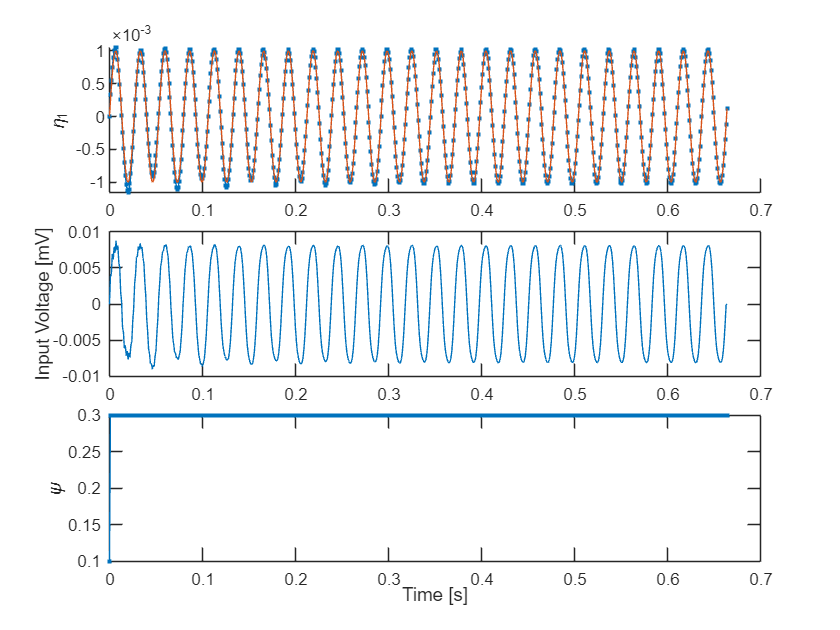

tiledlayout(3, 1, "TileSpacing","compact")
nexttile();
hold on;
plot(t_all, x_all(:, 1), ".-")
plot(t_all, model.eta_star(t_all))
ylabel("\eta_1");
nexttile;
plot(t_all, v_all./1000);
ylabel("Input Voltage [mV]");
nexttile;
plot(t_all, a_all(:,1), ".-")
xlabel("Time [s]");
ylabel("\psi");

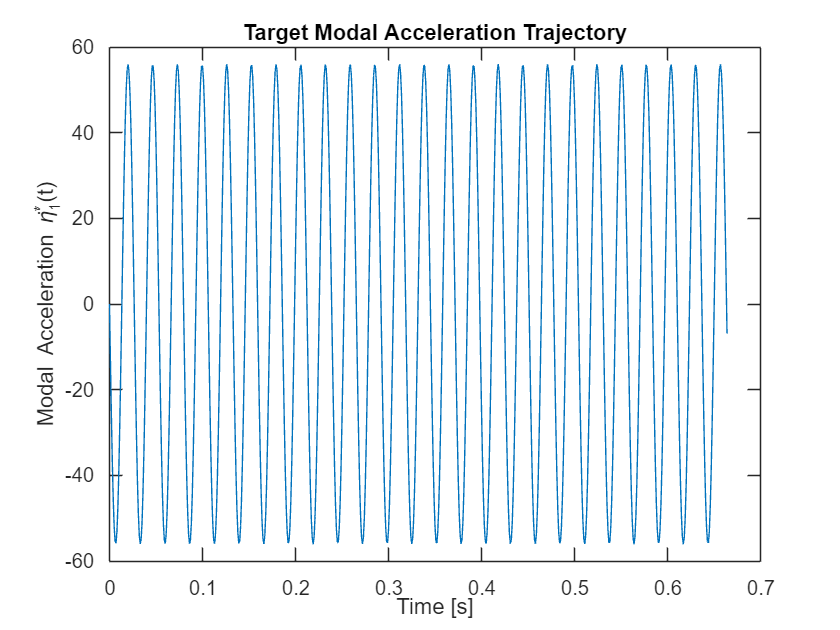

% Set A and B target harmonics
A_vec_target = zeros(model.harmonics, 1);
B_vec_target = zeros(model.harmonics, 1);
B_vec_target(1) = A_target;  % fundamental sine term

% Precompute harmonic frequencies
harmonics = (1:model.harmonics)';
omega_h = omega * harmonics;  % [harmonics x 1]

% Define eta_star(t) and eta_ddot_star(t)
model.eta_star = @(t) A_vec_target.' * cos(omega_h * t) + B_vec_target.' * sin(omega_h * t);
model.eta_ddot_star = @(t) - (A_vec_target .* omega_h.^2).' * cos(omega_h * t) ...
                          - (B_vec_target .* omega_h.^2).' * sin(omega_h * t);

% Plot eta_ddot_star
figure;
plot(t_all, arrayfun(model.eta_ddot_star, t_all))
xlabel('Time [s]')
ylabel('Modal Acceleration \etä^*_1(t)')
title('Target Modal Acceleration Trajectory')

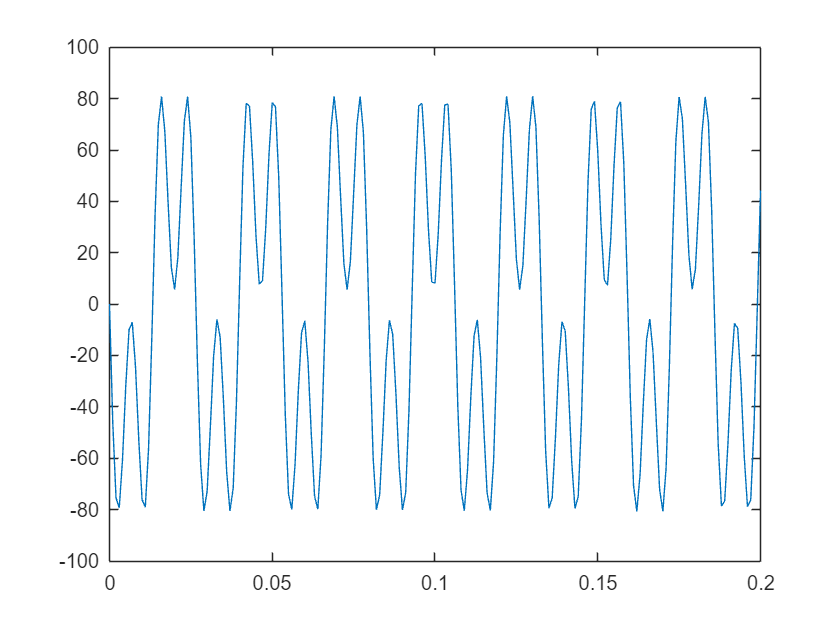

amp_err = 1.6351

amp_err = 0.9237

amp_err = 1.0203

amp_err = 0.9951

ans = "within tolerance > model.k1 = 1.5411"

% === CBC Iteration ===
max_iter = 20;
tol = 0.01;
harmonics = model.harmonics;

% for cbc_iter = 1:max_iter
    % Simulate again with fixed eta_star and gain-shaped controller
    % (reuse your existing loop, or call a function if modularized)
A_vec_target = [0; 0; 0];
B_vec_target = [1; 0; 0.1].*0.001;



% Recompute eta_star and eta_ddot_star using updated target vectors
omega_h = omega * (1:harmonics)';
model.eta_star = @(t) A_vec_target.' * cos(omega_h * t) + B_vec_target.' * sin(omega_h * t);
model.eta_ddot_star = @(t) - (A_vec_target .* omega_h.^2).' * cos(omega_h * t) ...
                      - (B_vec_target .* omega_h.^2).' * sin(omega_h * t);

figure;
test_t = (0:Ts:0.2)';
plot(test_t, arrayfun(model.eta_ddot_star, test_t))
% Control gains
model.k1 = 1;
model.k2 = 0.1;
model.Ts = Ts;
psi = 0.1;
psi_lim = 0.3;
a_all(1) = psi;

a_gain_shaping

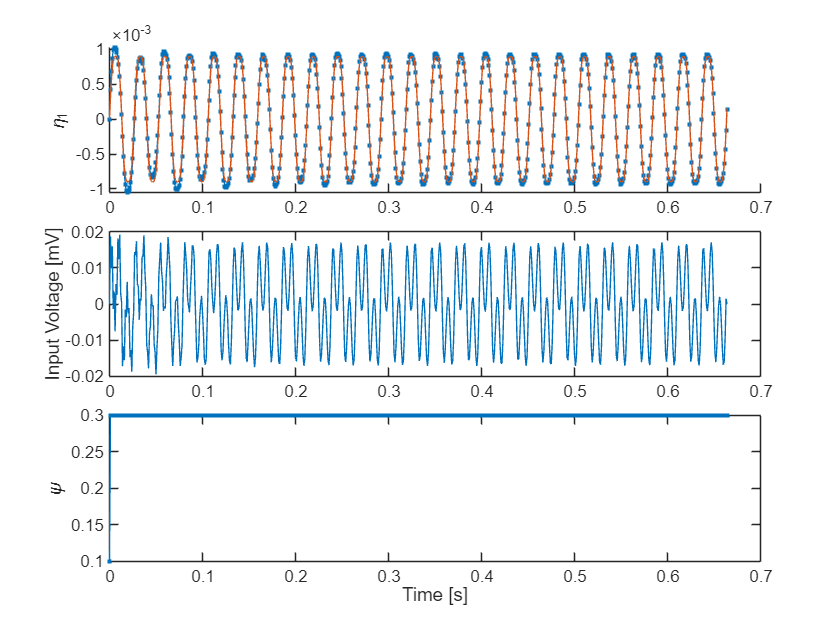

ans = 1.5411